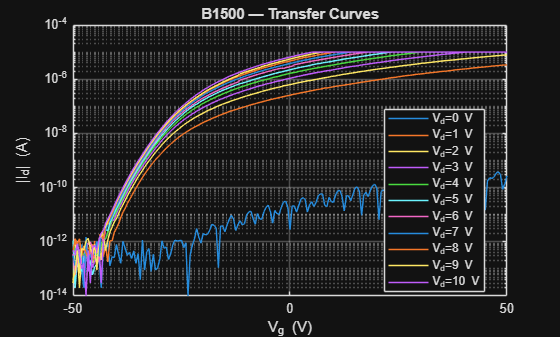

% Auto-detect everything, plot by default:
out1 = import_clarius_csv("C:\Users\Admin\Documents\SDA_Export\# Transfer Curve [CHIP012_O7(3) ; 10_7_2025 9_56_45 PM].csv");

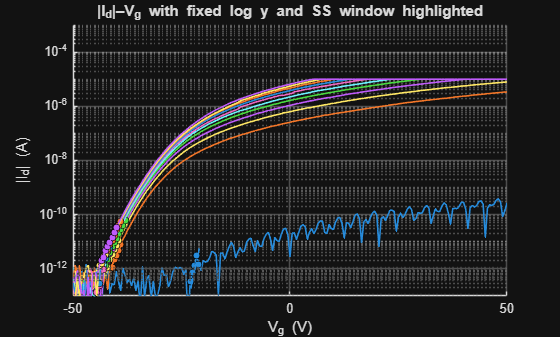

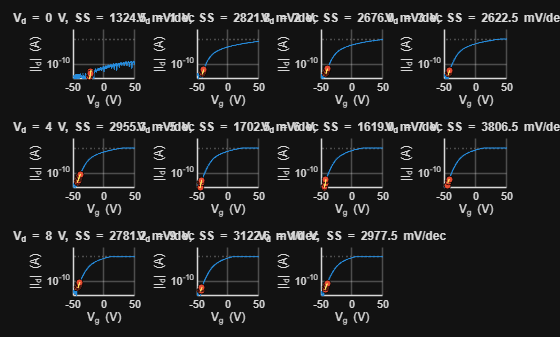

res = analyze_transfer_curves(out1, ...
    "YLim",[1e-13,1e-3], ...
    "DoPlot",true, ...
    "SmoothingPts",5, ...
    "PeakFrac",0.8, ...
    "IoffFrac",3, ...
    "PadVg",0.1, ...
    "MinWinPts",6);

res.Summary

ans = 11×6 table
    Vd    SS_mV_per_dec    Vg_left    Vg_right    Ioff_est     slope_dec_per_V
    __    _____________    _______    ________    _________    _______________

     0       1324.5         -23.5        -21        1.1e-13        0.75499    
     1       2821.8         -41.5        -39        6.5e-13        0.35439    
     2         2676           -42      -39.5        4.9e-13         0.3737    
     3       2622.5         -43.5        -41        6.1e-13        0.38131    
     4       2955.3           -43        -38       4.45e-13        0.33838    
     5       1702.5         -45.5      -42.5       3.65e-13        0.58737    
     6         1619         -44.5        -42       5.35e-13        0.61768    
     7       3806.5           -44      -41.5        6.5e-13        

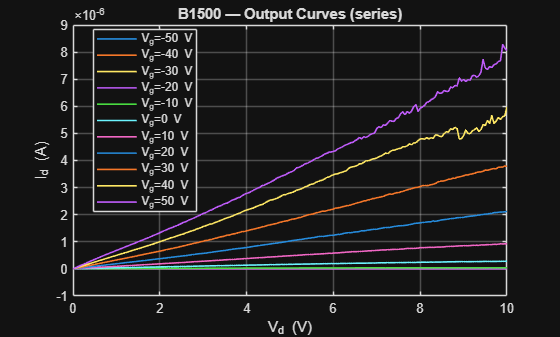

% Force output-curve series, plot on:
out2 = import_clarius_csv("C:\Users\Admin\Documents\SDA_Export\! Output Curve [CHIP012_P15(1) ; 7_10_2025 10_59_16 pm].csv", ...
                    FileType="output_series", Plot=true);

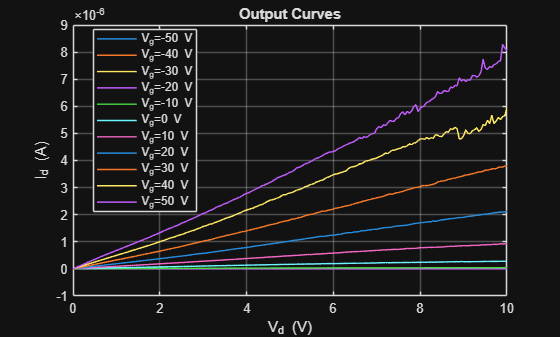

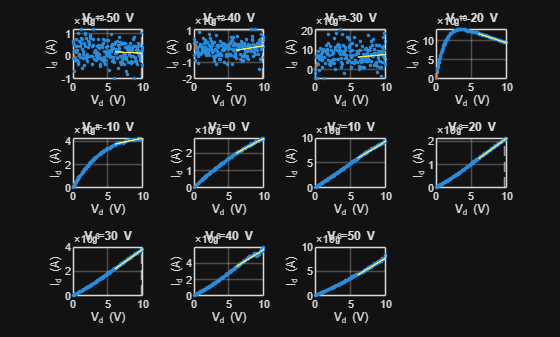

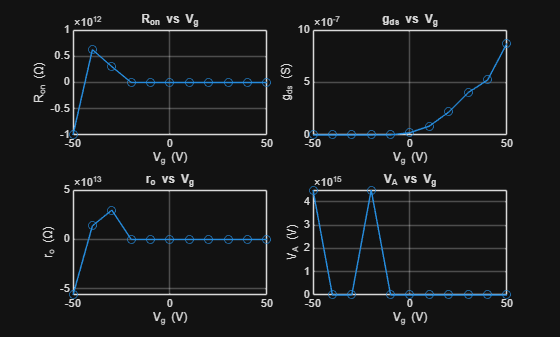

% 2) 进行输出曲线分析（多曲线或单曲线均可）
res = analyze_output_curves(out2, ...
    "VdLinMax", 0.1, ...        % 线性区上限（|Vd|<=0.1 V）
    "VdSatFrac", 0.6, ...        % 饱和区从 max(|Vd|) 的 60% 开始
    "DoPlot", true, ...          % 是否绘图（输出曲线图/拟合、gds/ro/V_A 等）
    "WLCOX", [10e-6, 1e-6, 1e-2], ... % [W, L, Cox] 可选，开启二次项长沟道拟合 (SI units)
    "UseQuadFit", true ...       % 是否进行小Vd二次拟合以估计 mu 与 Vth
);


% 3) 查看关键结果表
res.Summary  % 每个Vg一行（单曲线时就一行）

ans = 11×13 table
    Vg         Ron        dId_dVd_lin      gds_sat          ro           Id_sat        lambda          VA        Vds_knee_est        mu          Vth          A           Vgt   
    ___    ___________    ___________    ___________    ___________    ___________    _________    __________    ____________    __________    _______    __________    ________

    -50    -9.9946e+11    -1.0005e-12    -1.7775e-14    -5.6258e+13      1.521e-13     -0.11687    4.5036e+15        9.75        6.6968e-10    -50.091    6.6968e-11    0.091397
    -40 

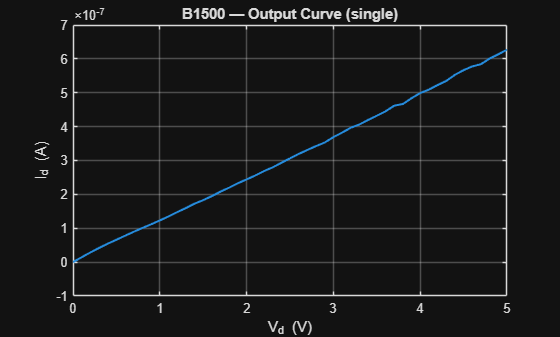

% Single output curve, no plot:
out3 = import_clarius_csv("Quick Check [(4) ; 7_10_2025 10_53_53 pm].csv", ...
    FileType="output_single", Plot=true);